## SHALLOW LEARNING

#### Playing with MATLAB's FITRNET Function

Inbuilt function to train a regression neural net

This appears to just be an ANN

rng("default")

N = 15000; %datapoints
m = 10; %num input features
input_data = [rand(N,m)] %input data normalised to btwn 0 and 1

input_data =     0.8147    0.2858    0.8252    0.1839    0.6388    0.3175    0.8937    0.2068    0.0886    0.3919
    0.9058    0.9312    0.0908    0.0488    0.2237    0.6382    0.8162    0.4302    0.4828    0.6212
    0.1270    0.7999    0.2064    0.5280    0.1693    0.2119    0.9474    0.9661    0.9015    0.4001
    0.9134    0.3311    0.7932    0.6577    0.3909    0.4541    0.2403    0.8127    0.5778    0.4569
    0.6324    0.7374    0.6817    0.3300    0.4590    0.5029    0.5797    0.6967    0.9693    0.3711
    0.0975    0.5674    0.4700    0.1683    0.8454    0.7209    0.1888    0.1507    0.4572    0.4465
    0.2785    0.0161    0.8978    0.1655    0.5333    0.5400    0.3513    0.8656    0.8015    0.2468
    0.5469    0.4255    0.4085    0.0459    0.0713    0.1541    0.6063    0.7257    0.3339    0.0212
    0.9575    0.0294    0.6585    0.2291    0.3536    0.1219    0.6446    0.5820    0.1271    0.1138
    0.9649    0.7842    0.9584    0.5768    0.9280    0.5349    0.6153    0.12


powers = randi([1,6],[1,m])

powers =      5     3     5     1     5     1     6     2     5     6


coeffs = [randn(m,1)]

coeffs =     0.6616
   -0.1329
    1.6312
    1.6487
   -0.2863
    0.6266
    0.8173
   -0.9155
    0.0620
    1.6330


const = rand(1)

const = 0.2846

actual_model = @(X) X*coeffs+const + 0.2.*sin(X*coeffs);

[output_data, shift, scale] = normalize(actual_model(input_data))

output_data =     0.4975
   -0.4860
   -1.0178
    0.4903
   -0.1764
   -0.8510
   -0.8117
   -2.0834
   -0.6044
    2.5352


shift = 3.1847

scale = 0.8260


partition_variable = cvpartition(N, "Holdout",0.3);
trainingIndices = training(partition_variable);
trainInput = input_data(trainingIndices,:);
trainOutput = output_data(trainingIndices,:);

testIndices = test(partition_variable);
testInput = input_data(testIndices,:);
testOutput = output_data(testIndices,:);


allModels = {};
i = 1;
lambda = [1e-8,1e-7, 1e-6,1e-5, 2e-5, 1e-4, 2e-4, 5e-4, 1e-3, 2e-3, 5e-3, 0.01, 0.02, 0.04, 0.08, 0.16, 0.32, 0.64, 1.28];

for L = drange(lambda)
    allModels(i) = {fitrnet(trainInput, trainOutput, 'Standardize', false, ...
    'LayerSizes', [5,5], 'Lambda', L)};
    i = i+1;
end

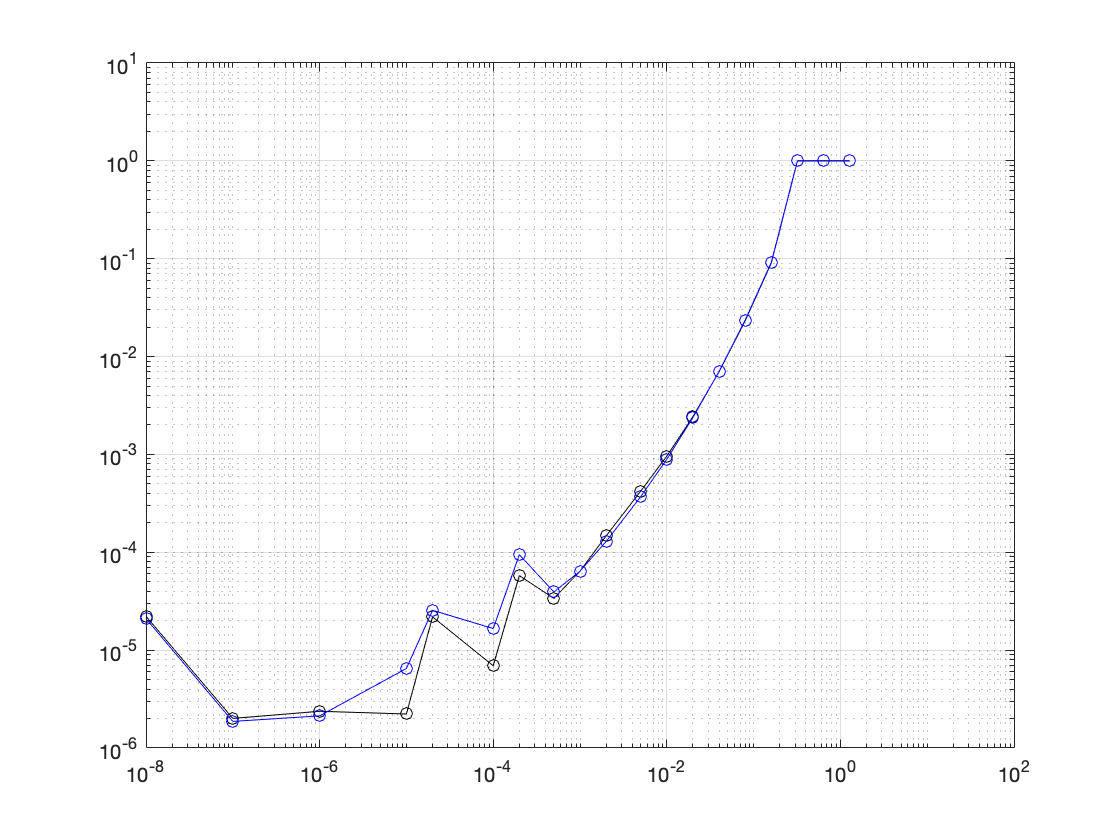


trainLoss = [];
testLoss = [];
for i=1:length(lambda)
    trainLoss(i) = loss(allModels{i}, trainInput, trainOutput);;
    testLoss(i) = loss(allModels{i}, testInput, testOutput);
end
clf
loglog(lambda, trainLoss, '-ok')
hold on
loglog(lambda, testLoss, '-ob')

grid on

InputCheck = rand([1,10])

InputCheck =     0.3521    0.9207    0.4475    0.2944    0.1910    0.2613    0.4617    0.2123    0.5310    0.4583


fprintf('Actual -> %.4f', actual_model(InputCheck))

Actual -> 2.7672

fprintf('Predicted -> %.4f', predict(allModels{3}, InputCheck)*scale+shift)

Predicted -> 2.7667

#### Playing with Patternnet

Same example as above

The perform function uses MSE but seems to be a lot higher than just calculating the MSE myself??

net = patternnet([5,5]);
% net.numInputs = m;
net.layers{1}.transferFcn = 'purelin';
net.layers{2}.transferFcn = 'purelin';
net.layers{3}.transferFcn = 'purelin';
% net.performParam.regularization = 1e-4;
net.performFcn = 'mse';
% net.inputConnect = [ones(1,m); zeros(2,m)];
% net.trainFcn = 'trainbfg';
% view(net)
% trainInputCell = mat2cell(trainInput', [ones(1,m)], [length(trainInput)]);
% trainOutputCell = mat2cell(trainOutput', [ones(1,1)], [length(trainOutput)]);
% 
% testInputCell = mat2cell(testInput', [ones(1,m)], [length(testInput)]);
% testOutputCell = mat2cell(testOutput', [ones(1,1)], [length(testOutput)]);

% net = train(net, trainInput', trainOutput')
% perform(net, testInput', testOutput')


mse_history = [];
training_data_sizes = floor(logspace(0,4,12));
for i=training_data_sizes
    tempnet = net; %must reset net between iterations
%     trainInputCell = mat2cell(trainInput(1:i,:)', [ones(1,m)], [i]);
%     trainOutputCell = mat2cell(trainOutput(1:i,:)', [ones(1,1)], [i]);

    tempnet = train(tempnet, trainInput(1:i,:)', trainOutput(1:i,:)');
%     [i, perform(tempnet, trainInput, trainOutput), perform(tempnet, testInput, testOutput)]
    mse_history = [mse_history; mean((trainOutput' - tempnet(trainInput')).^2), mean((testOutput' - tempnet(testInput')).^2)];
end
net = tempnet;

ans = 0

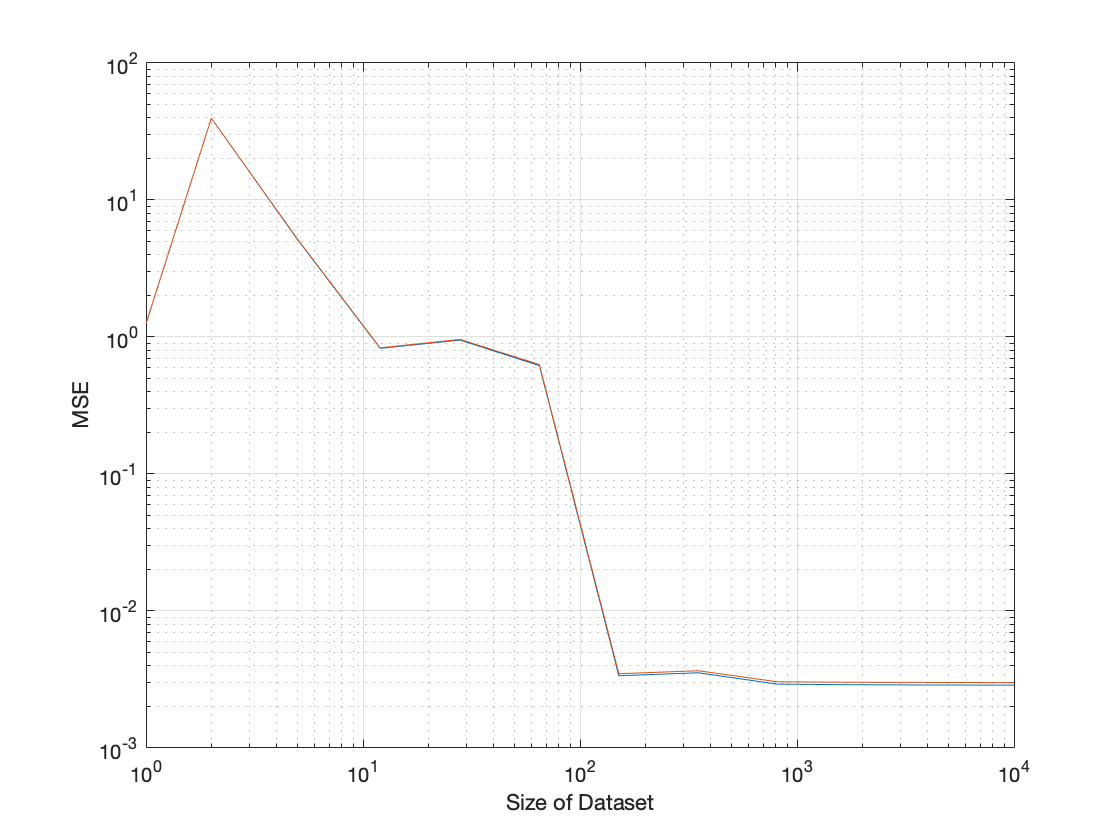

clf
loglog(training_data_sizes, mse_history(:,1))
hold on
loglog(training_data_sizes, mse_history(:,2))
grid on
xlabel("Size of Dataset")
ylabel("MSE")

InputCheck = rand([10,1]);
fprintf('Actual -> %.4f', actual_model(InputCheck'))

Actual -> 3.2673

fprintf('Predicted -> %.4f', tempnet(InputCheck)*scale+shift)

Predicted -> 3.2563

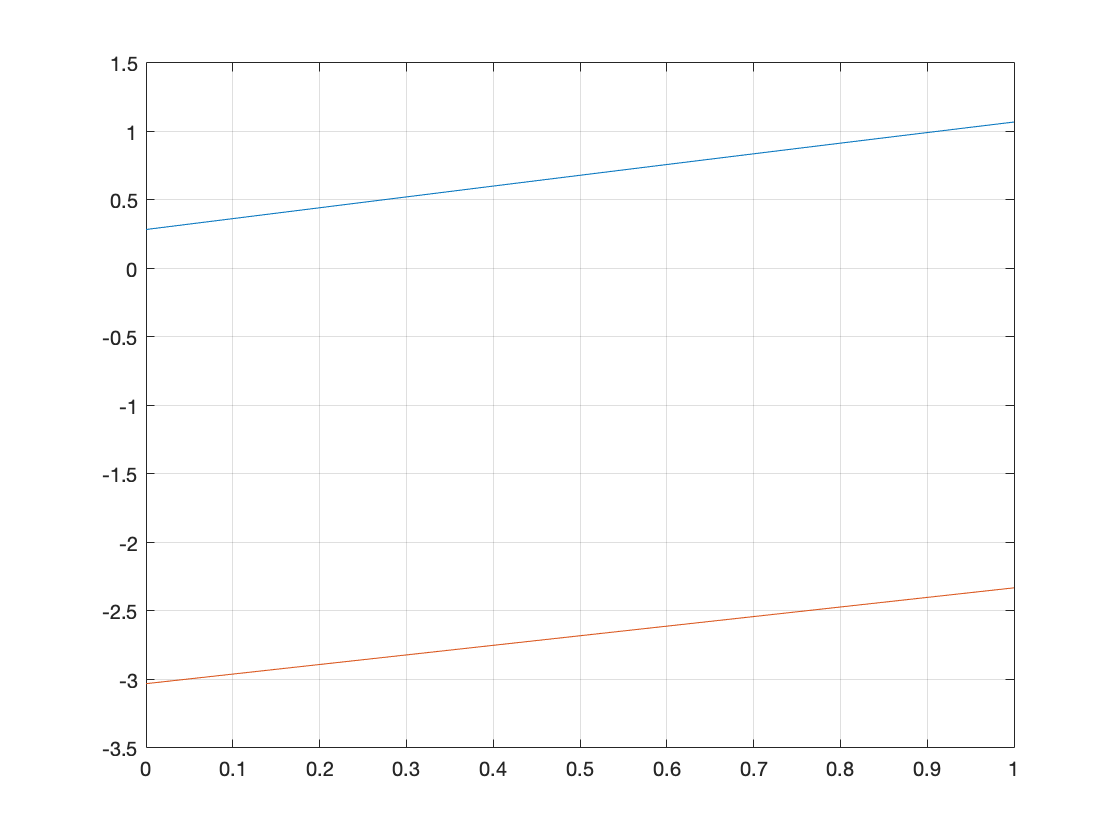


play_in = 0:0.05:1;
clf
plot(play_in, actual_model([play_in', zeros(length(play_in),m-1)]))
hold on
plot(play_in, net([play_in', zeros(length(play_in),m-1)]'))
grid on

#### Random Forest

Was used by Q. Xie in "Machine Learning Methods for Real-Time Blood Pressure Measurement Based on Photoplethysmography". There is a high level Matlab way to implement but requires reading up about the technique a bit and considering properties properly

#### LSTM 

Was used by L. Harfiya in "Continuous Blood Pressure Estimation Using Exclusively Photopletysmography by LSTM-Based Signal-to-Signal Translation". There is a high level Matlab way to implement but requires reading up about the technique a bit and considering properties properly

#### Support Vector Machine Regression

https://towardsdatascience.com/unlocking-the-true-power-of-support-vector-regression-847fd123a4a0

rsvmModel = fitrsvm(trainInput, trainOutput);

rsvmModel =   RegressionSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                    Alpha: [547×1 double]
                     Bias: -3.1686
         KernelParameters: [1×1 struct]
          NumObservations: 10500
           BoxConstraints: [10500×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [10500×1 logical]
                   Solver: 'SMO'


  Properties, Methods



frpintf("Converged? %i", rsvmModel.ConvergenceInfo.Converged)

rsvmModel

rsvmModel =   RegressionSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                    Alpha: [547×1 double]
                     Bias: -3.1686
         KernelParameters: [1×1 struct]
          NumObservations: 10500
           BoxConstraints: [10500×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [10500×1 logical]
                   Solver: 'SMO'


  Properties, Methods



i = randi(length(testInput));
fprintf("Actual Model -> %.4f", actual_model(testInput(i,:)))

Actual Model -> 4.3893

fprintf("Predicted Model -> %.4f", predict(rsvmModel, testInput(i,:)).*scale+shift)

Predicted Model -> 4.4683

#### Playing With Actual Data

inputdata = readtable('../physionet.org/inputFeatures.csv')

inputdata = 1302×613 table
       AI          CT        DiasPeakAmp    Freq001     Freq002      Freq003      Freq004      Freq005      Freq006      Freq007     Freq008     Freq009     Freq010     Freq011     Freq012     Freq013     Freq014     Freq015     Freq016     Freq017     Freq018     Freq019     Freq020     Freq021     Freq022     Freq023     Freq024     Freq025     Freq026     Freq027     Freq028     Freq029     Freq030     

inputdata = removevars(inputdata, {'Var613_1'});
inputdata_arr = table2array(inputdata);
outputdata = readtable('../physionet.org/outputFeatures.csv')

outputdata = 1302×606 table
     ABPBW     ABPPower    Freq001     Freq002      Freq003      Freq004      Freq005      Freq006     Freq007     Freq008     Freq009     Freq010     Freq011     Freq012     Freq013     Freq014     Freq015     Freq016     Freq017     Freq018     Freq019     Freq020     Freq021     Freq022     Freq023     Freq024     Freq025     Freq026     Freq027     Freq028     Freq029     Freq030     Freq031     

outputdata = removevars(outputdata, {'Var606_1'});
outputdata_arr = table2array(outputdata);

partition_variable = cvpartition(height(inputdata), "Holdout",0.3);
trainingIndices = training(partition_variable);
trainInput = inputdata(trainingIndices,:);
trainOutput = outputdata(trainingIndices,:);

testIndices = test(partition_variable);
testInput = inputdata(testIndices,:);
testOutput = outputdata(testIndices,:);

scatter(inputdata.PPGBW, outputdata.ABPBW)

% xtitle("PPG Bandwidth(norm)")
% ytitle("ABP Bandwidth(norm)")

clf
scatter(inputdata.CT, outputdata.MAP)


clf
scatter(inputdata.RespRate, outputdata.MeanSBP)

rsvmmodel = fitrsvm(trainInput, trainOutput.MeanSBP);

actualSBP = testOutput.MeanSBP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedSBP = predict(rsvmmodel, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedSBP-actualSBP)./actualSBP;
trainingError = (predict(rsvmmodel,trainInput)-trainOutput.MeanSBP)./trainOutput.MeanSBP;


clf
scatter(actualSBP, testingError.*100);
xlabel("SBP (mmHg)")
ylabel("% Error ")
grid on


fprintf("Average SBP test error: %.2f%%", mean(abs(testingError)).*100)

Average SBP test error: 8.52%

fprintf("Average SBP train error: %.2f%%", mean(abs(trainingError)).*100)

Average SBP train error: 28.46%

rnetModel = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
    'LayerSizes', [50,50], 'Lambda', 1);

trainingErrorRNET = (predict(rnetModel,trainInput)-trainOutput.MAP)./trainOutput.MAP;
testingErrorRNET = (predict(rnetModel,testInput)-testOutput.MAP)./testOutput.MAP;

fprintf("-- rANN --")

-- rANN --

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingErrorRNET)).*100)

Average MAP train error: 102.92%

fprintf("Average MAP test error: %.2f%%", mean(abs(testingErrorRNET)).*100)

Average MAP test error: 104.70%

## DEEP LEARNING

If feature extraction -> ML -> output fails we can try reproduce some of the studies that used the entire PPG waveform with a deep learning model

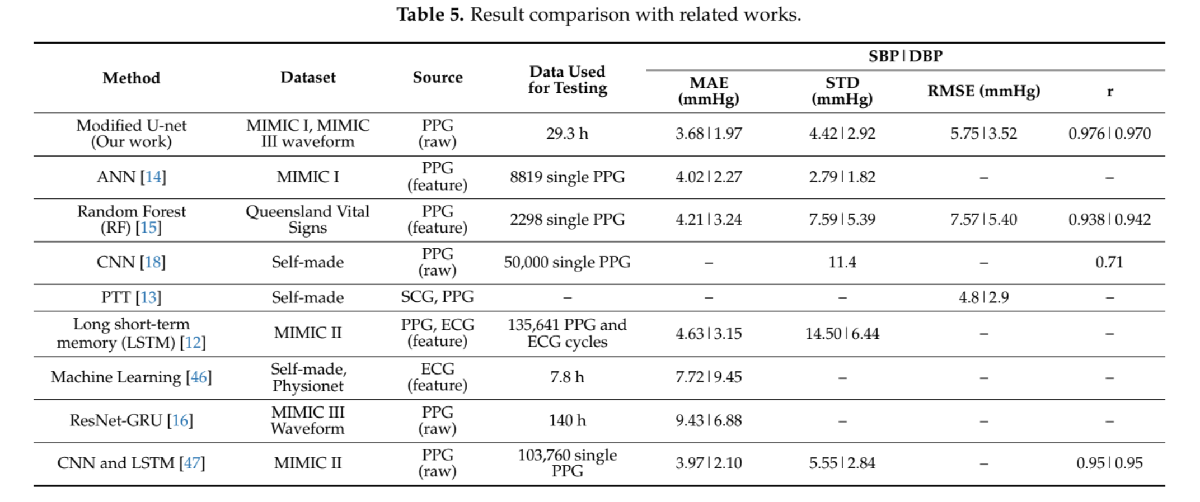

source: T. Athaya, S. Choi "An Estimation Method of Continuous Non-Invasive Arterial Blood Pressure Waveform Using Photoplethysmography: A U-Net Architecture-Based Approach" p. 13